clear
clc

levels = 0:9;
N = 20000 * 2.^levels;
M=2.^levels

M =      1     2     4     8    16    32    64   128   256   512


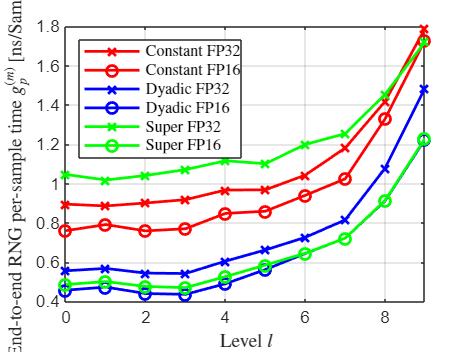


%%End-to-End per sample
levels = 0:9;
N = 20000 * 2.^levels;
M=2.^levels;


%Data copy and pasted from LUT_timings.cpp
CU32=[0.895;0.886;0.901;0.918;0.967;0.968;1.043;1.181;1.418;1.789];
CU16=[0.760;0.791;0.759;0.770;0.848;0.859;0.94;1.024;1.329;1.73];
LD32=[0.556;0.568;0.544;0.542;0.605;0.662;0.726;0.815;1.078;1.486];
LD16=[0.457;0.473;0.440;0.436;0.49;0.562;0.644;0.722;0.912;1.225];
LS32=[1.046;1.018;1.041;1.071;1.116;1.101;1.199;1.254;1.454;1.721];
LS16=[0.486;0.501;0.476;0.47;0.526;0.585;0.645;0.722;0.914;1.229];

for i=1:1:length(CU32)
speedup_c(i)=CU32(i)/CU16(i);
speedup_d(i)=LD32(i)/LD16(i);
speedup_s(i)=LS32(i)/LS16(i);
end

speedup_c;
speedup_d;
speedup_s;


figure
plot(levels,CU32,'-xr', 'LineWidth', 1.5, 'DisplayName', 'Constant FP32');
hold on
plot(levels,CU16,'-or', 'LineWidth', 1.5, 'DisplayName', 'Constant FP16');
plot(levels,LD32,'-xb', 'LineWidth', 1.5, 'DisplayName', 'Dyadic FP32');
plot(levels,LD16,'-ob', 'LineWidth', 1.5, 'DisplayName', 'Dyadic FP16');
plot(levels,LS32,'-xg', 'LineWidth', 1.5, 'DisplayName', 'Super FP32');
plot(levels,LS16,'-og', 'LineWidth', 1.5, 'DisplayName', 'Super FP16');
xlabel('Level $l$','Interpreter','latex')
ylabel('End-to-end RNG per-sample time $g_p^{(m)}$ [ns/Sample]','Interpreter','latex')
xlim([0 9]);
legend('Location','northwest','Interpreter', 'latex')

grid on
hold off

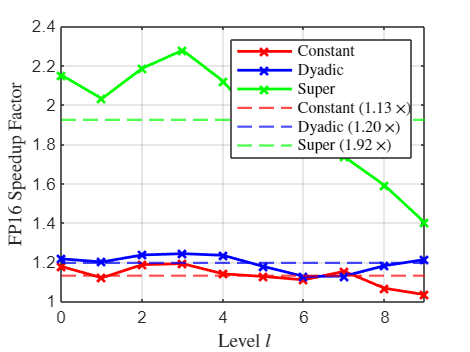


speedup_CU=CU32./CU16;
speedup_LD=LD32./LD16;
speedup_LS=LS32./LS16;


figure
h1=plot(levels,speedup_CU,'-rx', 'LineWidth', 1.5); hold on
h2=plot(levels,speedup_LD,'-bx', 'LineWidth', 1.5);
h3=plot(levels,speedup_LS,'-gx', 'LineWidth', 1.5);

muCU = mean(speedup_CU);
muLD = mean(speedup_LD);
muLS = mean(speedup_LS);

h4 = yline(muCU,'--r','LineWidth',1.2);
h5 = yline(muLD,'--b','LineWidth',1.2);
h6 = yline(muLS,'--g','LineWidth',1.2);

grid on
xlabel('Level $l$','Interpreter','latex')
ylabel('FP16 Speedup Factor','Interpreter','latex')
xlim([0 9]);

legend([h1 h2 h3 h4 h5 h6], ...
    'Constant', ...
    'Dyadic', ...
    'Super', ...
    sprintf('Constant $(%.2f\\times)$', muCU), ...
    sprintf('Dyadic $(%.2f\\times)$', muLD), ...
    sprintf('Super $(%.2f\\times)$',  muLS), ...
    'Location','northeast','Interpreter','latex');



mean(CU32)

ans = 1.0966

mean(CU16)

ans = 0.9810

mean(LD32)

ans = 0.7582

mean(LD16)

ans = 0.6361

mean(LS32)

ans = 1.2021

mean(LS16)

ans = 0.6554